# Range Estimation for Battery Electric Vehicle

Copyright 2022 - 2023 The MathWorks, Inc.

To return to the main page within this repository, [click here](matlab:open('ElectricVehicleDesignOverview.mlx')).

## Overview

The key challenges in the adoption of battery electric vehicles (BEV) lie in addressing the vehicle range anxiety, safety, and the total ownership cost for the consumer. You want to have a high range of the BEV, but this typically requires a larger battery on the vehicle. Batteries are the most expensive component on modern BEVs so sizing is important in determining the cost of the vehicle. To learn  how to size a high voltage (HV) battery pack, see the [Battery Pack Sizing Calculations for BEV](matlab:open('BEVBatterySizingMain.mlx')) example.

After sizing the battery pack, the range of the vehicle still depends on real world driving conditions. You get a different range while driving in hot climatic conditions to driving in sub-zero temperature conditions. The range also depends on the driver profile, including when the driving pattern is aggressive (demanding lots of instantaneous power) or relaxed (stable speeds or gradual acceleration). In this example, you use typical worst case driving profile scenarios to evaluate the range provided by a 400 V battery pack. You learn how to vary environmental and driving conditions to calculate the vehicle range and losses in its different subsystems.

Automotive companies run standard drive cycles to establish the BEV range rating. The drive cycles most used in the industry are new European drive cycle (NEDC), worldwide harmonized light vehicle test cycle (WLTC) and the environmental protection agency (EPA) cycle. You run these cycles under lab conditions. A typical NEDC has one phase of urban driving and one phase of non-urban driving. The total cycle time is 20 minutes and the maximum speed is 120 km/h.

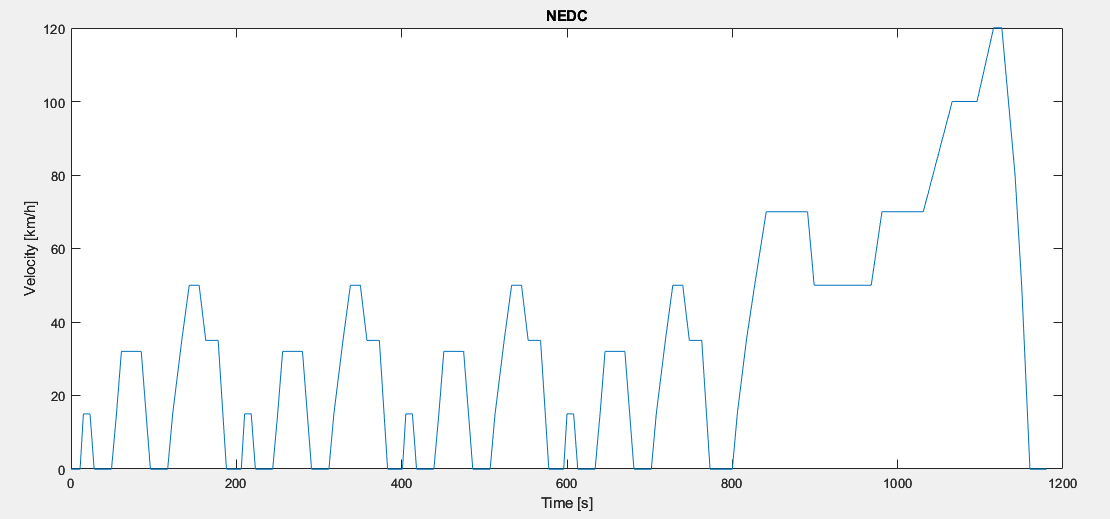

A typical worldwide harmonized light vehicle test procedure (WLTP) cycle has 4 dynamic phases: low, middle, high and extra high speed. The cycle time is 30 minutes and the maximum speed is 131 Km/h.

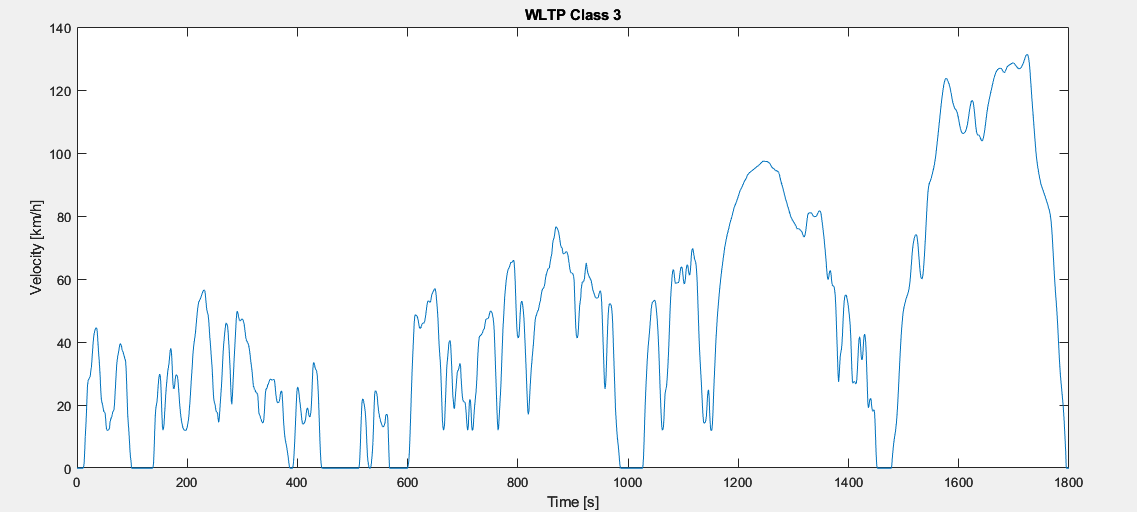

The EPA driving procedure puts the vehicle through multiple drive cycles. The two most used drive cycles are urban dynamometer driving schedule (UDDS) and highway fuel economy driving schedule (HWFEDS). UUDS is used for urban fuel economy and HWFET is used for highway fuel economy. 

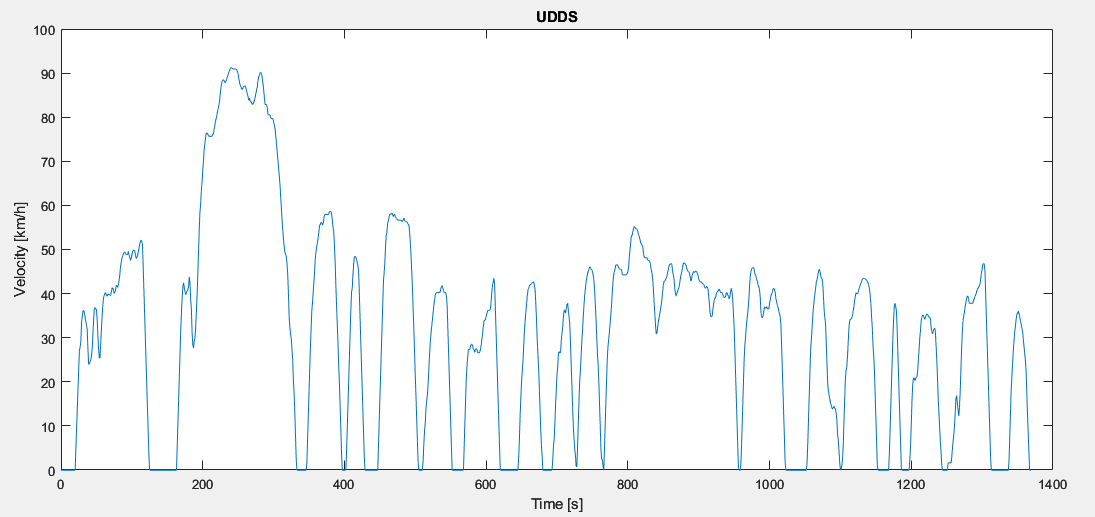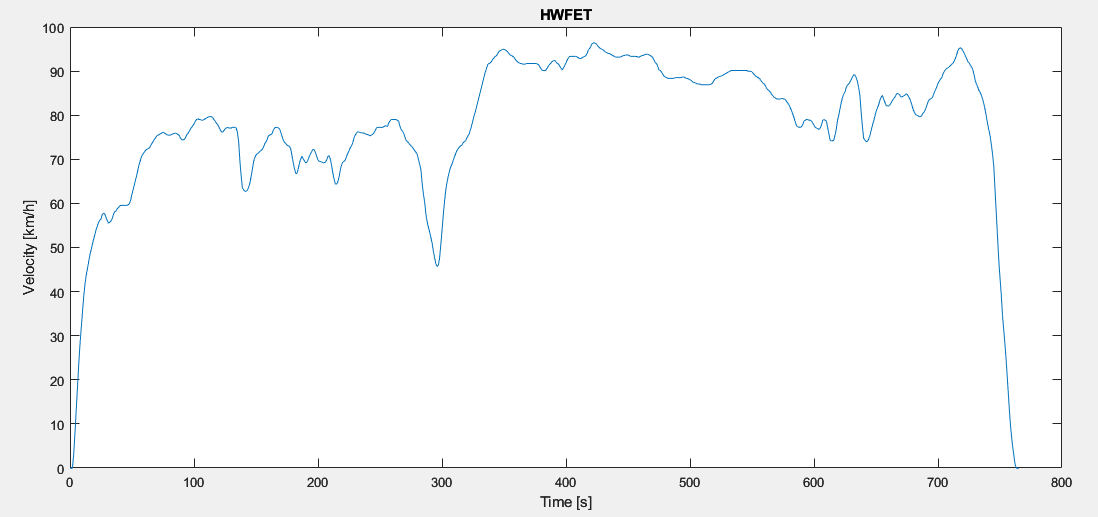

In this example, you run the NEDC and WLTC cycles with different ambient conditions and determine the range of the vehicle with a given battery size. To learn how to size a HV battery pack, see the  [Battery Pack Sizing Calculations for BEV](matlab:open('./BEVBatterySizingMain.mlx')) example.

You simulate the EPA multicycle driving procedure from 98% state of charge (SOC) to 0% SOC and use the energy consumed to estimate the range of the vehicle.

## Setup BEV Model

This model uses a BEV plant model that is an electrothermal system model for the entire vehicle. The battery pack is modeled using Simscape Battery™ pack builder and has two electric motors, one in front (the main drive) and one in rear (for boost and all wheel drive modes). For more information, see [Battery Electric Vehicle](http://bevmodelmain.mlx).

To simulate the model, you must download drive profile data from [Powertrain Blockset Drive Cycle Data](https://mathworks.com/matlabcentral/fileexchange/59683-powertrain-blockset-drive-cycle-data). 

Open the `BEVplantModel` model.

open_system("BEVplantModel")

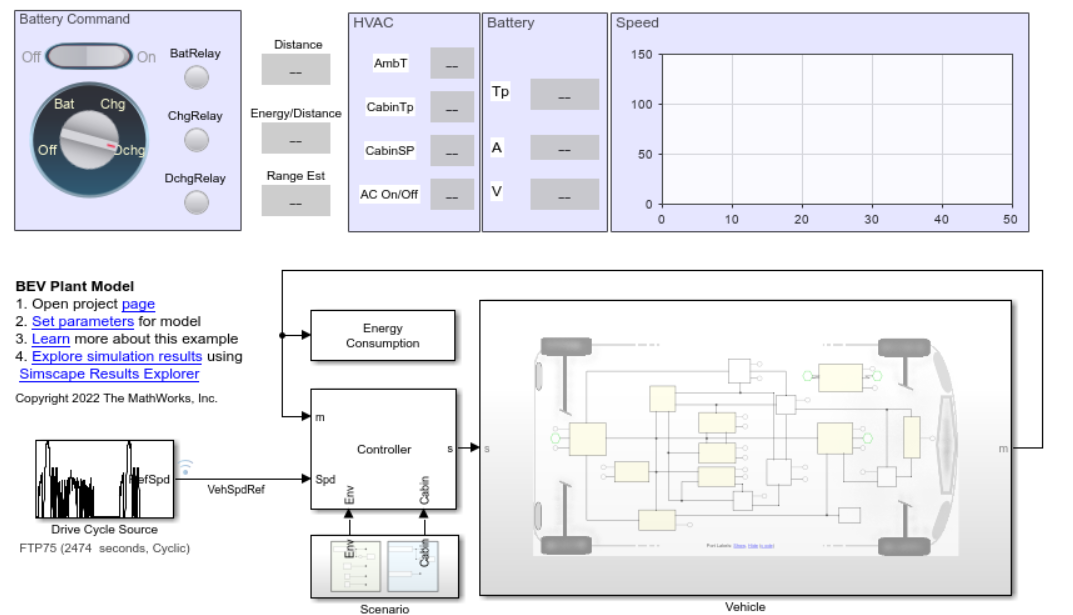

The driver control of the vehicle has an input for the vehicle speed setpoint in a Drive Cycle Source block*. *You set the value of variables which describe the ambient conditions, cabin setpoint, and initial temperature for the battery and coolant to simulate different scenarios.

To open the torque control subsystem, navigate to ***BEVplantModel/Controller/VehicleControl/TorqueControl.***

## 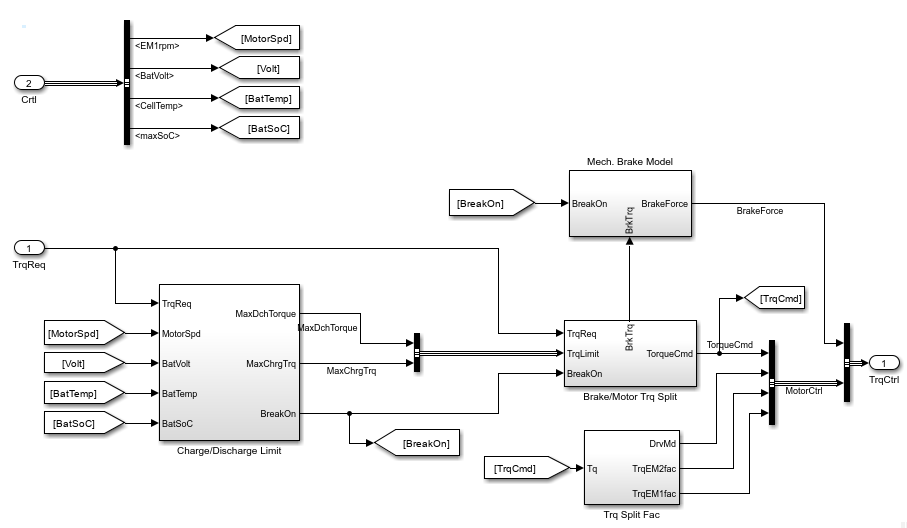

You can either manually select the drive cycle you want to run or you can set the parameters using a script. Set up the model for an NEDC drive cycle run.

driveCycle ='NEDC';             % drive cycle type, choose from drive cycle source block in model
SimulationTime ='1180';         % drive simulation time, put as per the drive cycle selection
speedBlock=find_system('BEVplantModel','Name','Drive Cycle Source'); % Get the block handle
try
    set(getSimulinkBlockHandle(speedBlock),'cycleVar',driveCycle);
catch
    error('To run this simulation, install the Powertrain Blockset Drive Profile Data');
end

Set value for the ambient temperature `ambient`(K), Coolant initial temperature `coolant_T_init`(K),  cabin setpoint temperature `CabinSpTp` (K) and cabin initial temperature `cabin_T_init` (K). Set `AConoff`*.*

vehicleThermal.ambient = 300;                % [K] Ambient temperature in
vehicleThermal.coolant_T_init = 30+273.15;   % [K] Coolant initial temperature
vehicleThermal.CabinSpTp = 20+273.15;        % [K] Cabin setpoint temperature
vehicleThermal.cabin_T_init = 30+273.15;     % [K] Cabin initial temperature
vehicleThermal.AConoff = 1;                  % AC on/off variable, 0 AC off, 1 AC On

Set the battery parameters for simulation.

%% Cell Electrical
battery.T_vec = [278 293 313];                          % [K] Temperature vector T
battery.AH = 34;                                        % [Ah] Cell capacity 
battery.AH_vec = [battery.AH battery.AH battery.AH];    % [Ah] Cell capacity vector AH(T)
battery.SOC_vec = [0, .1, .25, .5, .75, .9, 1];         % Cell state of charge vector SOC [-]
battery.initialPackSOC = 0.5;	                        % Pack intial SOC (-)

% Run parameter file for battery
batt_BatteryManagementSystem_param;
batt_packBTMSExampleLib_param;

## Define Environmental and Operating Conditions

Environmental conditions and heating, ventilation and air conditioning (HVAC) demands influence electric vehicle power consumption. When the vehicle runs in low temperatures, you need to heat the battery to the optimal temperature. The battery powers the HVAC system to heat the cabin. When the ambient temperature is very high the chiller needs to come in loop to cool the battery quickly. All these operations demand current from the battery and effect the range of the vehicle substantially. Since the vehicle range is rated under a fixed ambient condition of 25 degC, these extra demands from the battery  result in a lower range for the car than expected.

These non-powertrain demands effect the overall range of the vehicle. The vehicle is set up to be in an equilibrium state, with an initial temperature equal to the ambient temperature. The drive cycle runs once with an initial SOC of '75%'.

**Cold ambient Condition **

The ambient temperature is -5 degC.

- AC On — HVAC is on. The HVAC heating load and battery heating put a heavy demand on the battery.

- AC Off — HVAC is off and the battery heater is the auxiliary load.

**Hot ambient condition**

The ambient temperature is 35 degC.

- AC On — HVAC is on. The cabin cooling and battery chiller put a heavy demand on the battery.

- AC Off — HVAC is off and the battery chiller is the auxiliary load.

## Run Simulations

In this example, you use precomputed results from the NEDC and WLTP profiles to demonstrate the impact of various environmental conditions on the range calculation. To modify the results with NEDC, run the script detailing the [NEDC profile for different ambient conditions](matlab:open('BEVrangeEstimationNEDC.m')). Similarly, to modify the results with WLTP, run the script detailing the [WLTP profile for different ambient conditions](matlab:open('BEVrangeEstimationWLTC.m')).

MAT files store the results for the NEDC and WLTC cycles because the runtime is considerable.

For EPA range measurement you run a multicycle simulation. The simulation starts with the ambient temperature at 25 degC and 98% SOC and runs for multiple cycles of UDDS and HWFET until the battery is fully discharged. To run the simulation, refer to the script detailing the process [EPA multicycle drive](matlab:open('BEVrangeEstimationEPA.m')).

## Plot Estimated Range of BEV

**NEDC drive**

Load the results for NEDC profile runs.

load('NEDCrangeData.mat')
%Tabulated comparison of the run
NEDC.Case     = ["NEDC Low Temp, AC";"NEDC Low Temp, No AC";"NEDC High Temp, AC";"NEDC High Temp, No AC"];
NEDC.Range    = [NEDCloTpAC.RangeRating;NEDCloTpNoAC.RangeRating;NEDChiTpAC.RangeRating;NEDChiTpNoAC.RangeRating];
NEDC.Motor1   = [NEDCloTpAC.EM1energy;NEDCloTpNoAC.EM1energy;NEDChiTpAC.EM1energy;NEDChiTpNoAC.EM1energy];
NEDC.Motor2   = [NEDCloTpAC.EM2energy;NEDCloTpNoAC.EM2energy;NEDChiTpAC.EM2energy;NEDChiTpNoAC.EM2energy];
NEDC.Energy   = [NEDCloTpAC.Energy;NEDCloTpNoAC.Energy;NEDChiTpAC.Energy;NEDChiTpNoAC.Energy];
NEDC.HVAC     = [NEDCloTpAC.HVACenergy;NEDCloTpNoAC.HVACenergy;NEDChiTpAC.HVACenergy;NEDChiTpNoAC.HVACenergy];
NEDC.Aux      = [NEDCloTpAC.AuxEnergy; NEDCloTpNoAC.AuxEnergy; NEDChiTpAC.AuxEnergy; NEDChiTpNoAC.AuxEnergy];
rangeDataNEDC = array2table([NEDC.Range,NEDC.Energy,NEDC.Motor1,NEDC.Motor2,NEDC.HVAC,NEDC.Aux],...
           'VariableNames',{'Range (kms)','Energy (kWhr)','Motor1 Losses (kWhr)','Motor2 Losses (kWhr)','HVAC Losses (kWhr)','Aux. Losses (kWhr)'})

rangeDataNEDC = 4×6 table
    Range (kms)    Energy (kWhr)    Motor1 Losses (kWhr)    Motor2 Losses (kWhr)    HVAC Losses (kWhr)    Aux. Losses (kWhr)
    ___________    _____________    ____________________    ____________________    __________________    __________________

      227.24          1963.3               1223.5                  38.081                   648.13              53.204      
       338.3          1315.1               1223.5                  38.081               1.0475e-45              53.257      
      248.38            1796                 1224                  38.088                   357.75              175.78      
         310          1436.8               1224.1                  38.088              -7.0577e-47              174.28      


**WLTC drive**

Load the results for WLTC profile runs.

load('WLTCrangeData.mat')
%Tabulated comparison of the run
WLTC.Case     = ["WLTC Low Temp, AC";"WLTC Low Temp, No AC";"WLTC High Temp, AC";"WLTC High Temp, No AC"];
WLTC.Range    = [WLTCloTpAC.RangeRating;WLTCloTpNoAC.RangeRating;WLTChiTpAC.RangeRating;WLTChiTpNoAC.RangeRating];
WLTC.Motor1   = [WLTCloTpAC.EM1energy;WLTCloTpNoAC.EM1energy;WLTChiTpAC.EM1energy;WLTChiTpNoAC.EM1energy];
WLTC.Motor2   = [WLTCloTpAC.EM2energy;WLTCloTpNoAC.EM2energy;WLTChiTpAC.EM2energy;WLTChiTpNoAC.EM2energy];
WLTC.Energy   = [WLTCloTpAC.Energy;WLTCloTpNoAC.Energy;WLTChiTpAC.Energy;WLTChiTpNoAC.Energy];
WLTC.HVAC     = [WLTCloTpAC.HVACenergy;WLTCloTpNoAC.HVACenergy;WLTChiTpAC.HVACenergy;WLTChiTpNoAC.HVACenergy];
WLTC.Aux      = [WLTCloTpAC.AuxEnergy; WLTCloTpNoAC.AuxEnergy; WLTChiTpAC.AuxEnergy; WLTChiTpNoAC.AuxEnergy];
rangeDataWLTC = array2table([WLTC.Range,WLTC.Energy,WLTC.Motor1,WLTC.Motor2,WLTC.HVAC,WLTC.Aux],...
           'VariableNames',{'Range (kms)','Energy (kWhr)','Motor1 Losses (kWhr)','Motor2 Losses (kWhr)','HVAC Losses (kWhr)','Aux. Losses (kWhr)'})

rangeDataWLTC = 4×6 table
    Range (kms)    Energy (kWhr)    Motor1 Losses (kWhr)    Motor2 Losses (kWhr)    HVAC Losses (kWhr)    Aux. Losses (kWhr)
    ___________    _____________    ____________________    ____________________    __________________    __________________

       208.3          4517.9               3043.1                  408.62                   973.94              91.756      
      265.26          3542.6               3042.6                  408.58                4.671e-47              90.977      
      214.14          4394.3                 3043                  408.58                   555.09              387.18      
      246.71          3811.2                 3043                  408.57              -7.0577e-47              359.16      


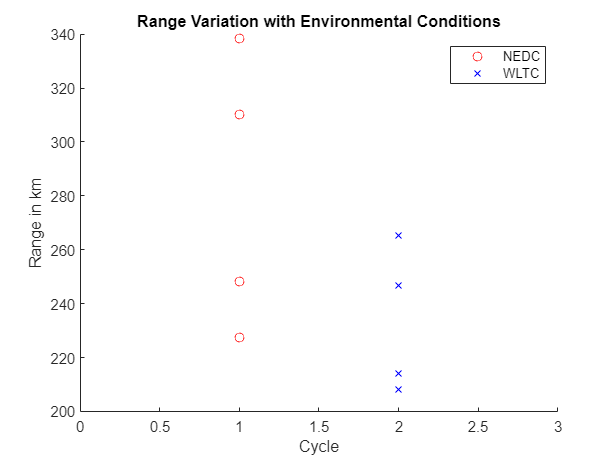

scatter(ones(1,length(WLTC.Range)),rangeDataNEDC.("Range (kms)"),'or');
hold on
scatter(2*ones(1,length(WLTC.Range)),rangeDataWLTC.("Range (kms)"),'xb');
legend('NEDC','WLTC')
xlim([0 3]);
ylabel('Range in km');xlabel('Cycle')
title('Range Variation with Environmental Conditions')
hold off

## Useful Links

[Electric Vehicle Design with Simscape](matlab:open('ElectricVehicleDesignOverview.mlx'))